**Computer Exercise 4.4.2**

The following program will analyze the interpolation of the function $f(x) = (x^2 +1)^{-1}$ by using 20 equally space nodes on the interval $[-5, 5]$ first with nodes defined by $x_i = 5\cos(i\pi/20)$ (i.e. Chebyshev Nodes) and then with nodes defined by $x_i = 5\cos((2i + 1)\pi/42)$ where $0 \leq i \leq 20$.

f = @(x) (x.^2 +1).^(-1); %initiate function

%initiate both sets of node points
nodes1 = zeros(1, 21);
nodes2 = zeros(1, 21);

for i = 1:21
    nodes1(i) = 5*cos(((i-1)*pi)/(20));
    nodes2(i) = vpa(5*cos(((2*i + 1)*pi)/(42)));
end

% final node points in the second set of nodes
% are equal so I will nudge the final node point
% so the program doesn't yield infinities for 
% yvals2
nodes2(21) = nodes2(21) + (10^(-15)); 

data1 = f(nodes1);
data2 = f(nodes2);

xvals = linspace(-5, 5, 41); %x values to evaluate functions

yvals1 = interp_func(xvals, nodes1, data1); %p1(x) evaluated at xvals
yvals2 = interp_func(xvals, nodes2, data2); %p2(x) evaluated at xvals
yvals3 = f(xvals); %f(x) evaluated at xvals

error1 = abs(yvals1 - yvals3);
error2 = abs(yvals2 - yvals3);

Results for the node points given by $x_i = 5\cos(i\pi/20)$:

table1 = table(xvals', yvals1', yvals3', error1', ...
    'VariableNames', {'x', 'p1(x)', ...
    'f(x)', 'error1'});
disp(table1)

      x            p1(x)                  f(x)                  error1       
    _____    __________________    __________________    ____________________

       -5    0.0384615384615385    0.0384615384615385                       0
    -4.75    0.0422824977197068    0.0424403183023873    0.000157820582680421
     -4.5    0.0457196254657967    0.0470588235294118     0.00133919806361509
    -4.25     0.056769278871316    0.0524590163934426      0.0043102624778734
       -4    0.0572664536391745    0.0588235294117647     0.00155707577259024
    -3.75    0.0606194623090939    0.0663900414937759     0.00577057918468203
     -3.5    0.0768541918171254    0.0754716981132075     0.00138249370391784
    -3.25    0.0943647104785681    0.0864864864864865     0.00787822399208159
       -3     0.102647028813403                   0.1     0.00264702881340348
    -

...

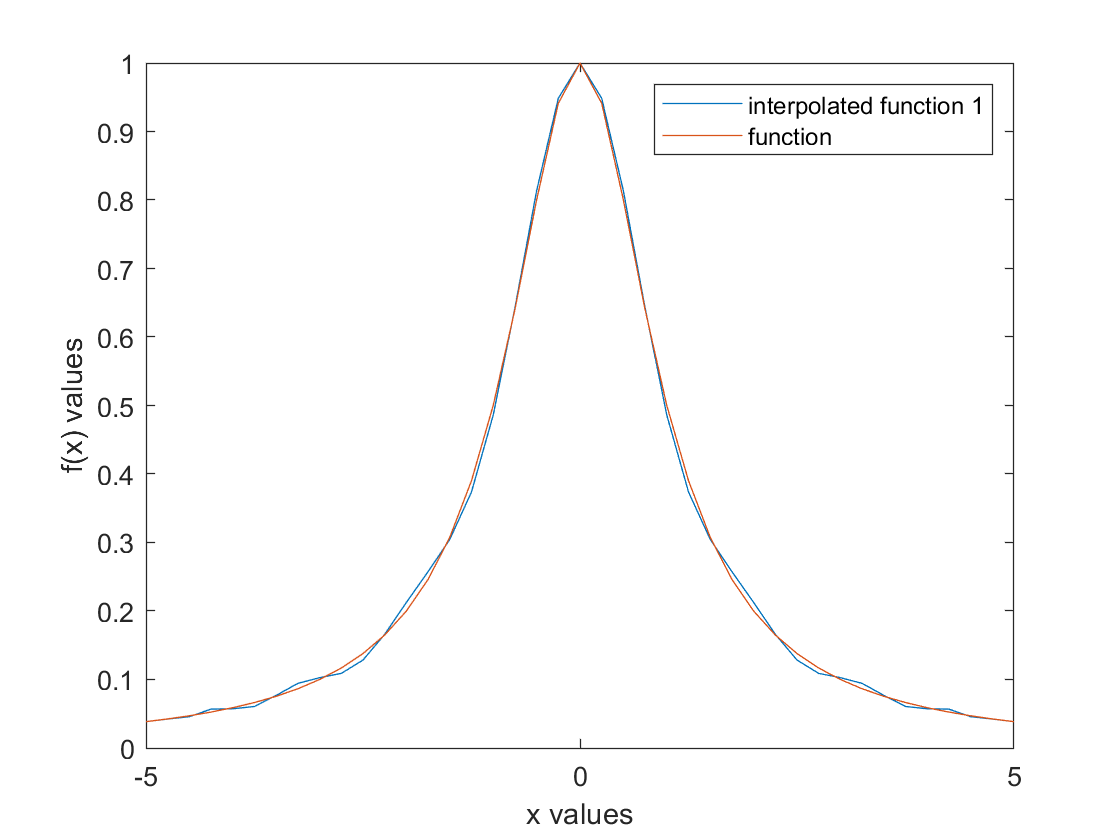

h = plot(xvals, yvals1, xvals, yvals3);
xlabel('x values')
ylabel('f(x) values')
legend('interpolated function 1', 'function')%, "Location","southeast")

From the plot, we can see that Chebyshev node points work really well. However, at the tails, we can observe a slight amount of oscillation.

Results for the node points given by $x_i = 5\cos((2i + 1)\pi/42)$

table2 = table(xvals', yvals2', yvals3', error2', ...
    'VariableNames', {'x', 'p2(x)', ...
    'f(x)', 'error2'});
disp(table2)

      x            p2(x)                 f(x)                  error2       
    _____    _________________    __________________    ____________________

       -5         0.0380859375    0.0384615384615385    0.000375600961538464
    -4.75        0.04248046875    0.0424403183023873    4.01504476127343e-05
     -4.5      0.0469970703125    0.0470588235294118    6.17532169117641e-05
    -4.25      0.0526123046875    0.0524590163934426    0.000153288294057377
       -4      0.0589599609375    0.0588235294117647    0.000136431525735295
    -3.75      0.0660400390625    0.0663900414937759    0.000350002431275934
     -3.5       0.075439453125    0.0754716981132075    3.22449882075443e-05
    -3.25       0.087158203125    0.0864864864864865    0.000671716638513509
       -3       0.101318359375                   0.1     0.00131835937499999
    -2.75      0

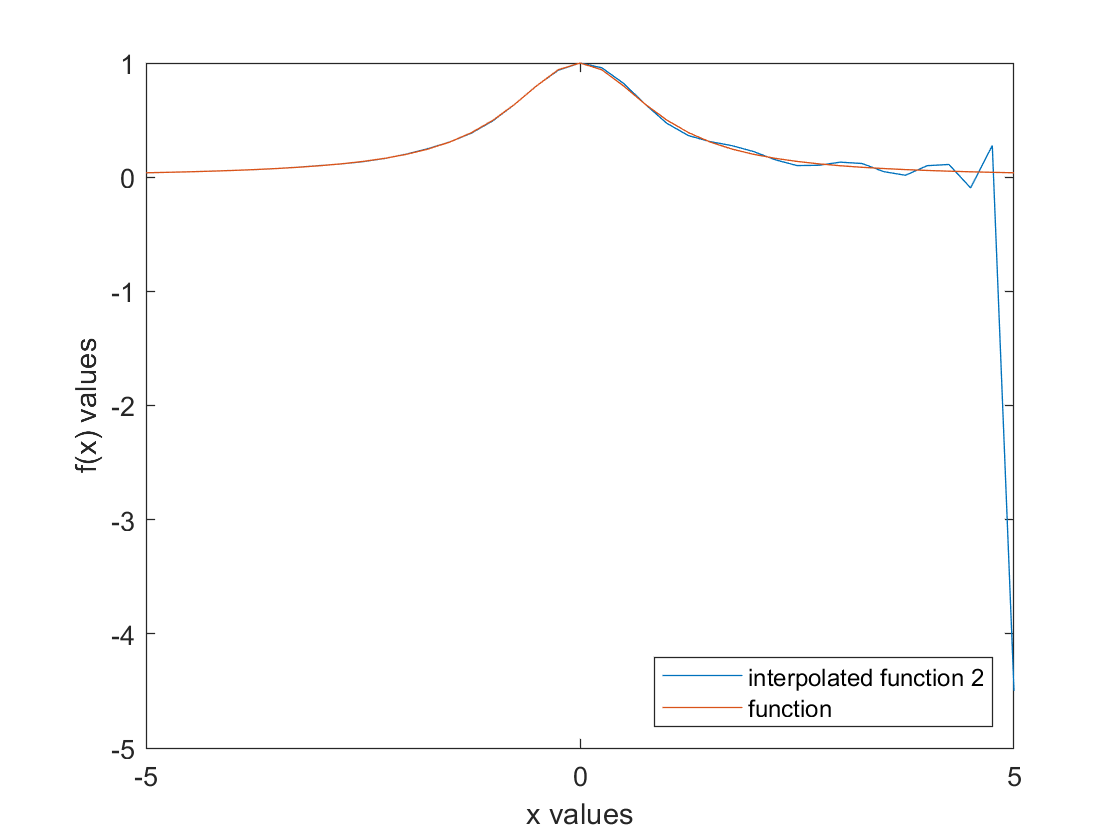

h = plot(xvals, yvals2, xvals, yvals3);
xlabel('x values')
ylabel('f(x) values')
legend('interpolated function 2', 'function', "Location","southeast")

The second set of node points appear to have the effect of confining the oscillation effects only to the right tail of the plot. Nevertheless, the estimations appear to be good for points far enough to the left of $x=5$.

function sum = interp_func(x, nodes, data) %Lagrange Interpolation
    sum = 0;
    for i = 1:length(nodes)
        prod = 1;
        for j = 1:length(nodes)
            if j ~= i
                prod = prod .* ( (x - nodes(j))./(nodes(i) - nodes(j)) );
                %fprintf('node difference = %8.8f \n', (nodes(i) - nodes(j)))
            end
        end
        sum = sum + data(i).*prod;
    end
end